# Elaborato FFT.

## Analisi della concetrazione di ${\mathrm{CO}}_2$.

Si analizzano i dati relativi alla concentrazione di ${\mathrm{CO}}_2$ nell'atmosfera. Si effettuano il grafico del fenomeno e il periodogramma. Si tenta di ricostruire il segnale in ingresso utilizzando nel primo caso la componente continua e le due armoniche con potenza maggiore e nel secondo caso la componente continua e le quattro armoniche con potenza maggiore.

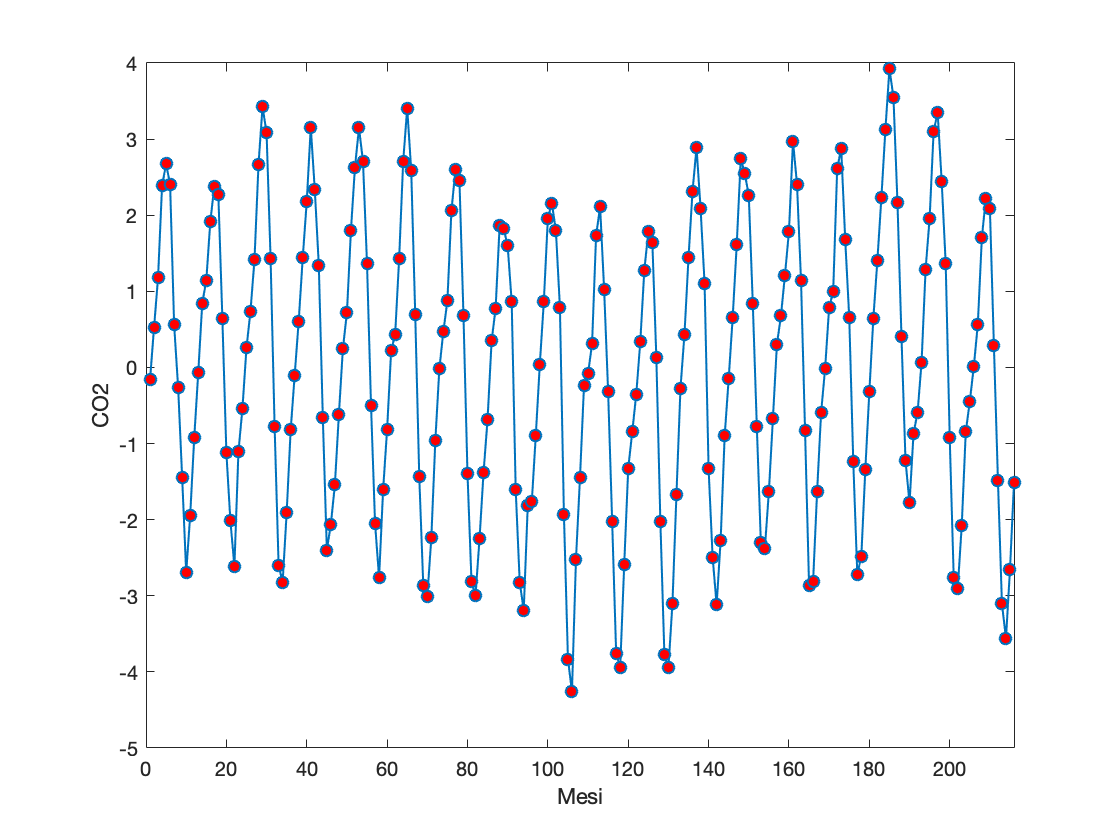

load -ASCII co2.mat 
t = co2(:,1)';
y = co2(:,2)';

%Grafico del fenomeno
figure('Name',"Concentrazione di CO2 nell'atmosfera");
plot(t,y,'-o','LineWidth',1,'MarkerFaceColor','r')
xlim([0 216]);
xlabel('Mesi');
ylabel('CO2');

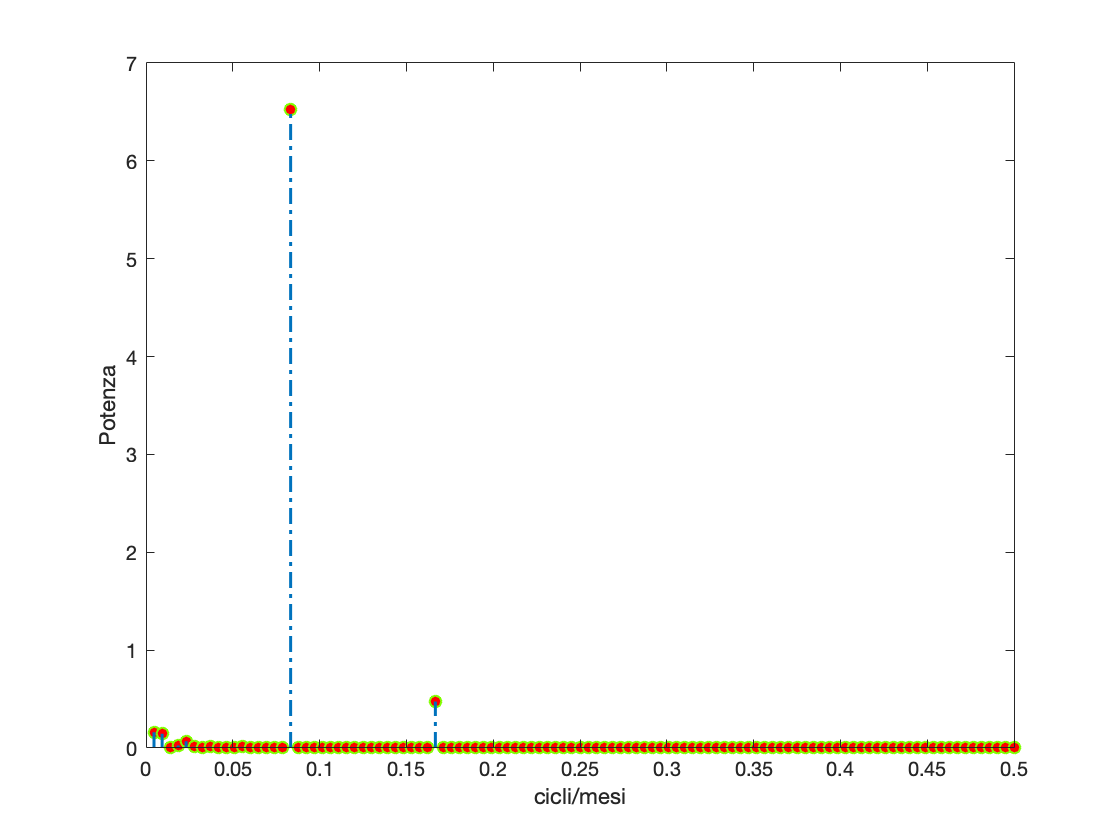


%Analisi dello spettro
Fs = 1;
N = length(y);
Y = fft(y)*2/N;
%Y1 = Y;
%Y1(1) = [];

f = (1:floor(N/2))*Fs/N; %segnale reale, per simmetria si opera con le frequenze da 1 a N/2
%pow = (2*abs(Y1(1:floor(N/2))/N)).^2;
pow = (abs(Y(2:floor(N/2+1)))).^2;

%Periodogramma
figure('Name','Periodogramma');
stem(f,pow,'fill','LineStyle','-.','LineWidth',1,'MarkerFaceColor','red','MarkerEdgeColor',[0.5 1 0]);
xlabel('cicli/mesi');
ylabel('Potenza');

sorted_pow = sort(pow,'descend');
maxpow = sorted_pow(1); %calcolo della massima potenza
maxpow2 = sorted_pow(2); %calcolo della seconda potenza maggiore
freq1 = f(pow == maxpow) %frequenza alla quale la potenza è massima

freq1 = 0.0833

freq2 = f(pow == maxpow2) %frequenza corrispondente alla seconda potenza maggiore

freq2 = 0.1667

ind1 = find(Y==Y(pow == maxpow));
ind1 = ind1+1 %indice corrispondente alla massima potenza, il vettore pow ha indici sfasati rispetto a Y (pow non considera la potenza della comp. continua)

ind1 = 19

abs(Y(ind1))^2

ans = 6.5265

ind2 = find(Y==Y(pow==maxpow2)) %indice corrispondente alla seconda potenza maggiore

ind2 = 36

ind2 = ind2+1

ind2 = 37

abs(Y(ind2))^2

ans = 0.4748

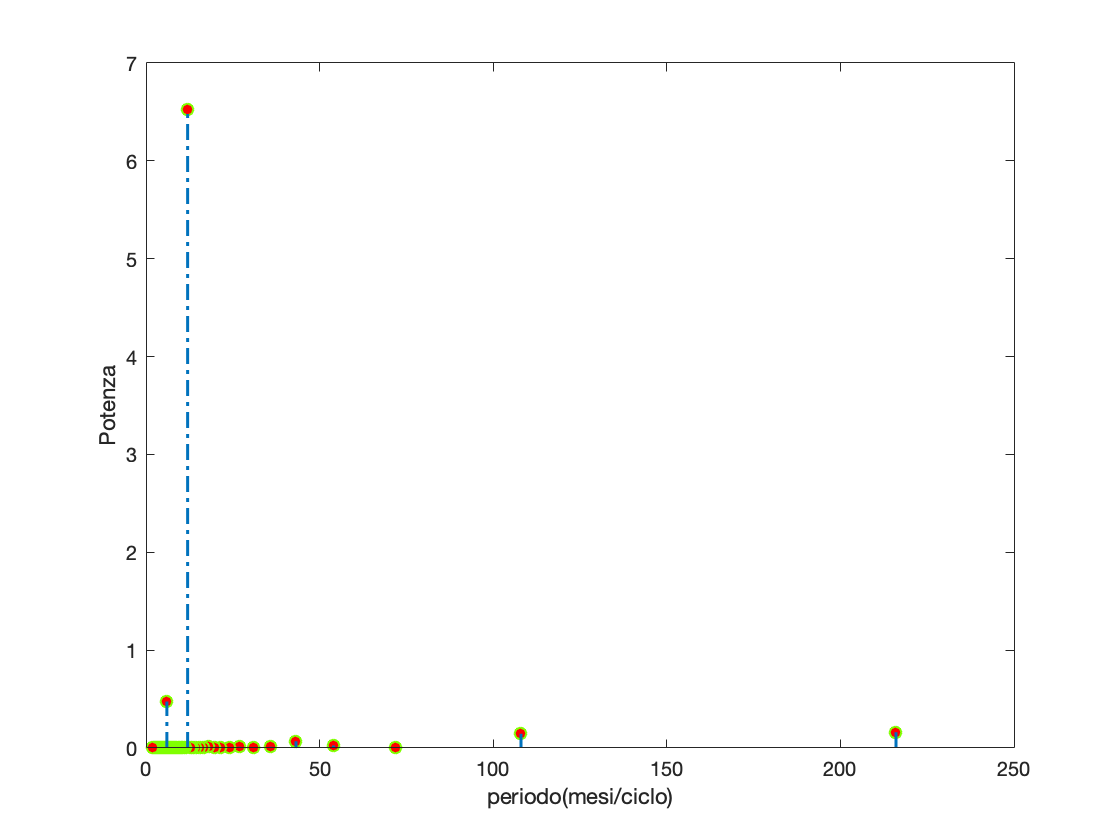

%si visualizza la potenza in funzione del periodo
figure('Name','Periodogramma');
p = 1./f;
stem(p,pow,'fill','LineStyle','-.','LineWidth',1,'MarkerFaceColor','red','MarkerEdgeColor',[0.5 1 0]);
xlabel('periodo(mesi/ciclo)');
ylabel('Potenza');


maxper = p(pow == maxpow); %periodo in cui il fenomeno raggiunge la massima potenza:
%maxper2 = p(pow == maxpow2); %periodo in cui il fenomeno raggiunge la seconda potenza maggiore

%Ricostruzione segnale mediante DC + 2 componenti maggiori
a = zeros(size(Y));
a(1) = Y(1);
a(ind1) = Y(ind1);
a(N-ind1) = Y(ind1);

% a(ind2) = Y(ind2);
% a(N-ind2) = Y(ind2);

xn = ifft(a)*N/2;
figure('Name','Ricostruzione segnale I');
plot(t,xn)

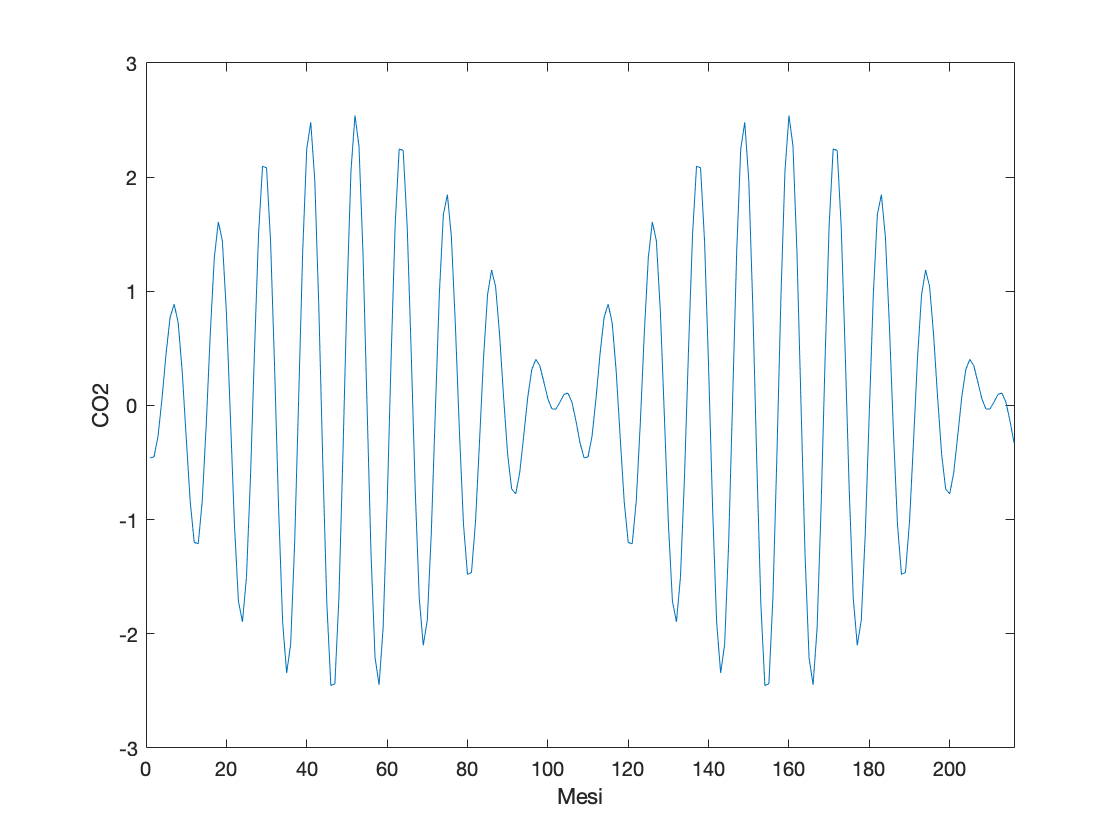

xlim([0 216]);
xlabel('Mesi');
ylabel('CO2');


% Ricostruzione segnale mediante DC + 4 componenti maggiori
b = zeros(size(Y));
b(1) = Y(1);
b(ind1) = Y(ind1);
b(N-ind1) = Y(ind1);
b(ind2) = Y(ind2);
b(N-ind2) = Y(ind2);
xr = ifft(b)*N/2;
figure('Name','Ricostruzione segnale II');
plot(t,xr)

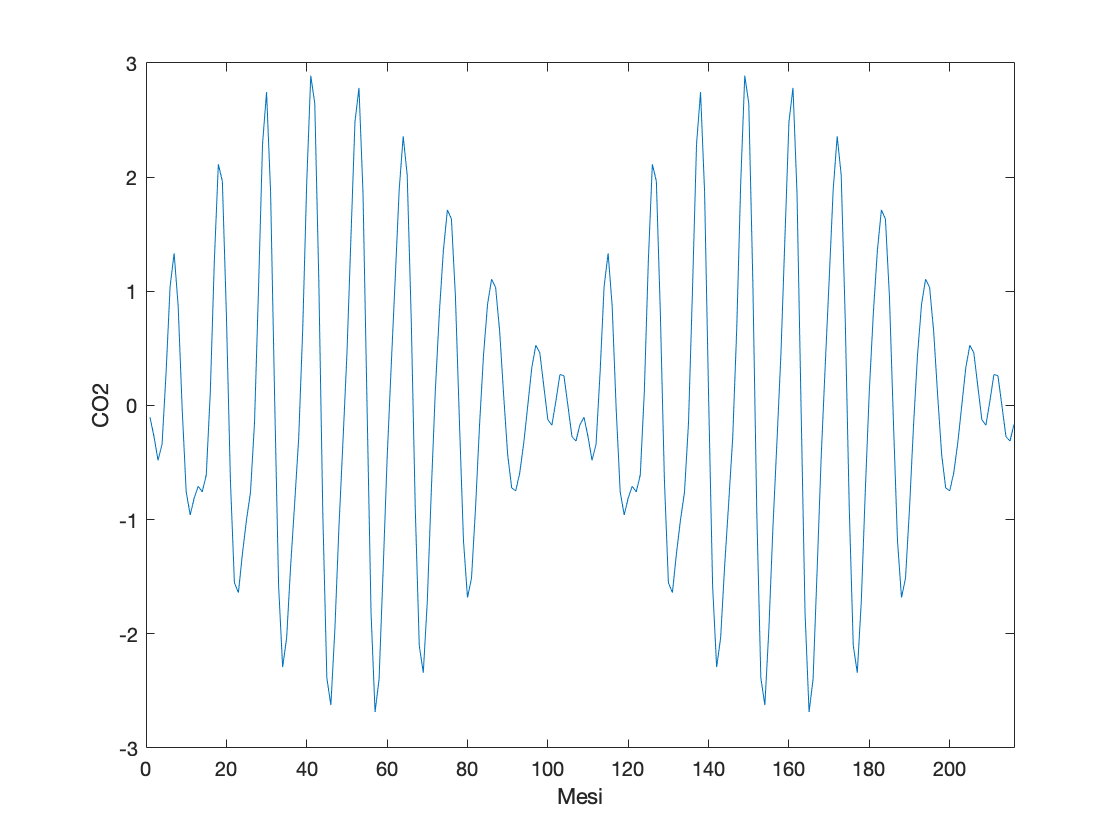

xlim([0 216]);
xlabel('Mesi');
ylabel('CO2');

## Segnale sonoro.

Di seguito si analizza il segnale sonoro presente nel file `vicru.mat` tramite periodogramma e spettrogramma. Analizzando lo spettrogramma, si individua il rumore e lo si elimina. Quindi si ricompone il segnale e lo si analizza nuovamente rifacendo il periodogramma e lo spettrogramma. Si scrive infine il brano nel file `vicruR.wav` .

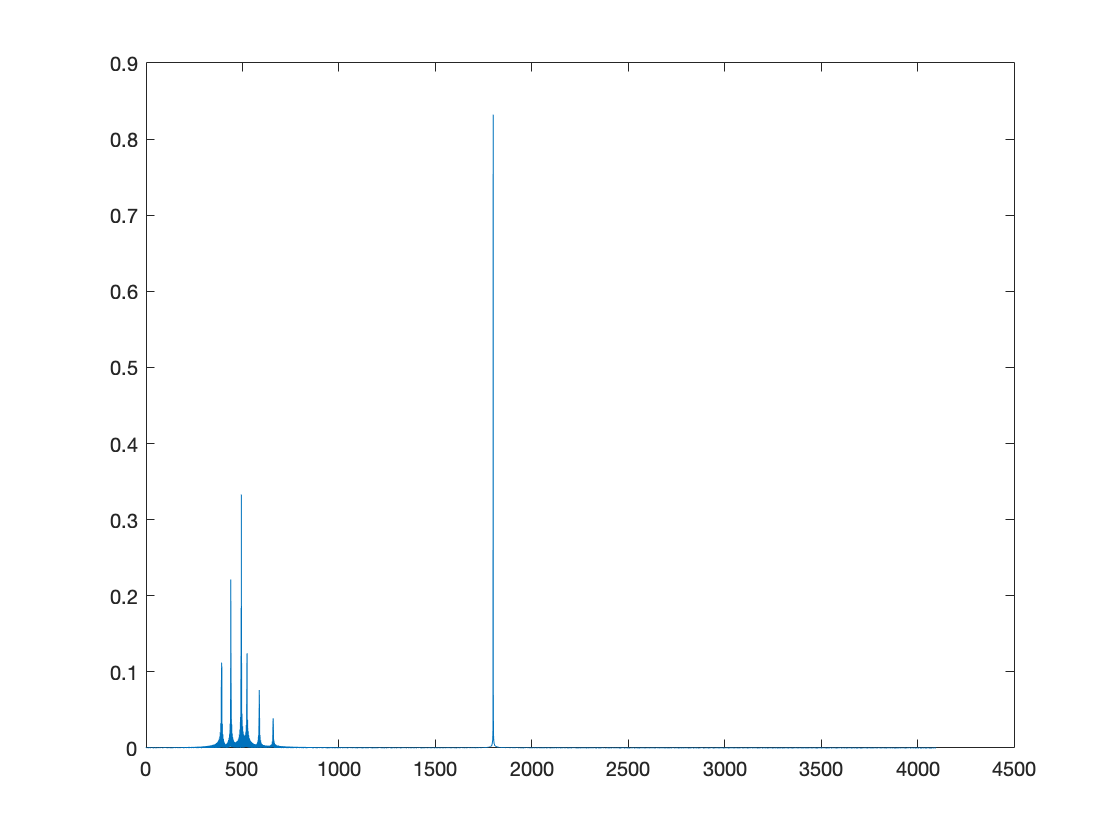

load vicru.mat
%soundsc(real(y)) %per eseguire il segnale audio

Fs = 8192;
n = length(y);
F = fft(y);
amp = 2*abs(F(1:floor(n/2)+1)/n);
f = (0:n/2)*Fs/n;

ys = y/max(abs(y));
audiowrite('ys.wav',ys,Fs);

figure('Name','Periodogramma');
plot(f,amp);

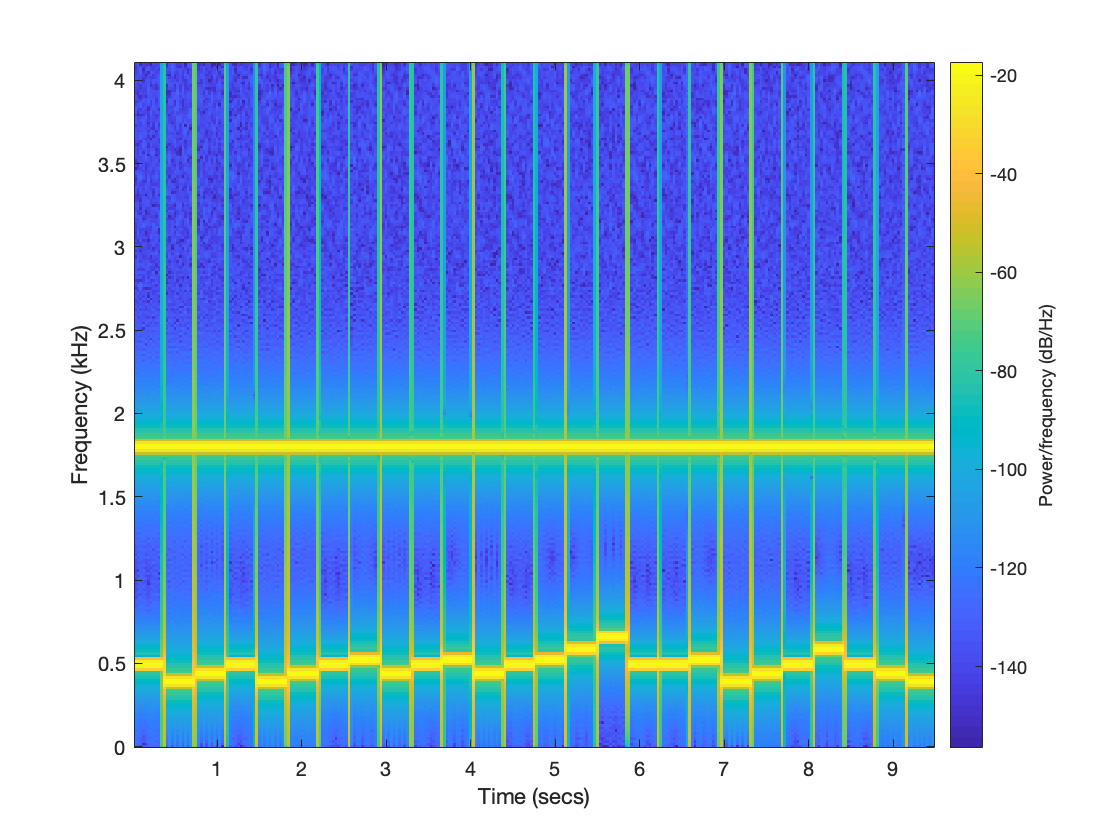

N = 512;
figure('Name','Spettrogramma');
spectrogram(y,blackman(N),floor(0.5*N),N,Fs,'yaxis');

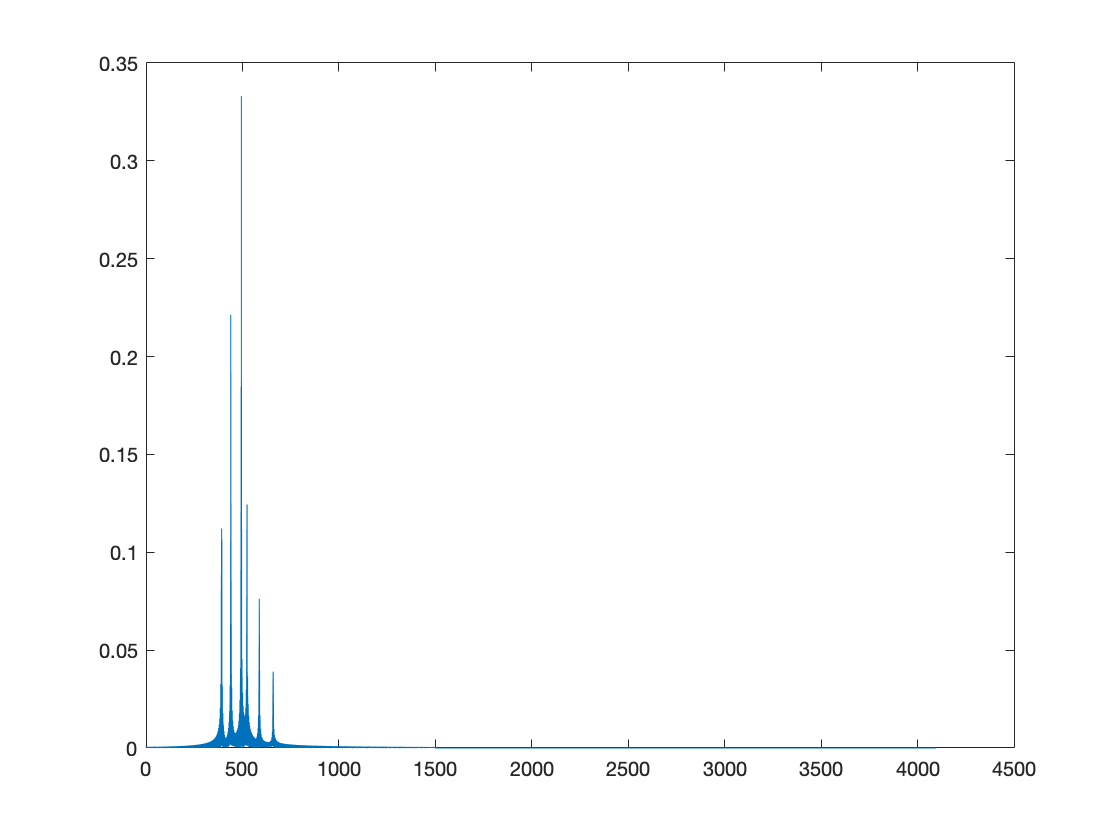

suono_filtrato = F;
ind = find(f>1500);
suono_filtrato(ind)=0;
suono_filtrato(n+2-ind)=0;

ampR = 2*abs(suono_filtrato(1:floor(n/2)+1)/n);
figure('Name','Periodogramma del segnale filtrato');
plot(f,ampR);

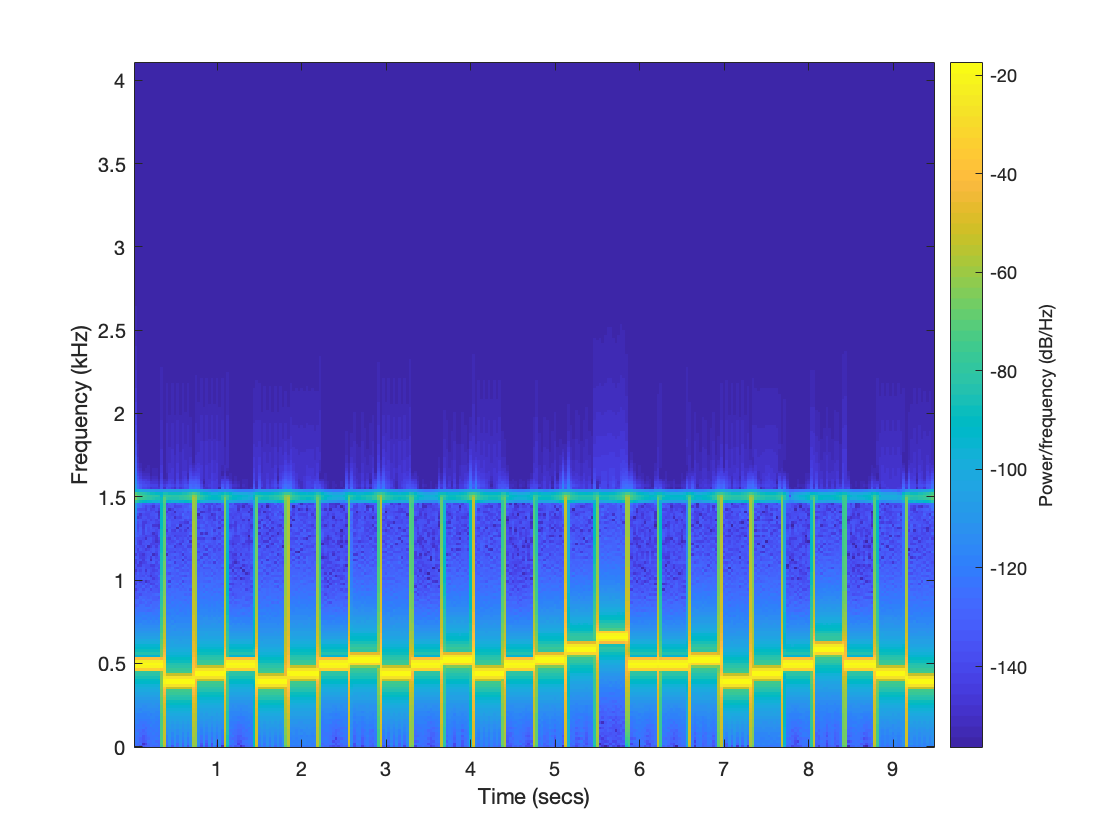

vicruR = ifft(suono_filtrato);

figure('Name','Spettrogramma del segnale filtrato');
spectrogram(vicruR,blackman(N),floor(0.5*N),N,Fs,'yaxis');

vicruR = vicruR/max(abs(vicruR));
audiowrite('vicruR.wav',vicruR,Fs);
%soundsc(real(vicruR)) %per eseguire il segnale audio